clear all, close all;

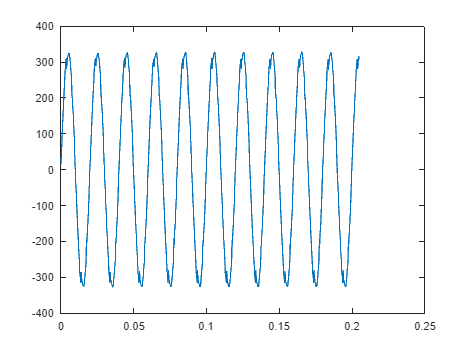

csv_read;

%csv_analize;
SAMPLING_FREQ = (50*16*16);
BUFFER_LEN = 2048;

out_floating = sim("float_model.slx");
out_fixed = sim("fixed_model.slx");
out_hdl = sim("hdl_model.slx");

close all;

FFT_float = out_floating.floating_model.signals(1);
RMS_float = out_floating.floating_model.signals(2);
MIN_float = out_floating.floating_model.signals(3);
MAX_float = out_floating.floating_model.signals(4);
THD_float = out_floating.floating_model.signals(5);
BUF_float = out_floating.floating_model.signals(6);

FFT_fixed = out_fixed.fixed_point.signals(1);
RMS_fixed = out_fixed.fixed_point.signals(2);
MIN_fixed = out_fixed.fixed_point.signals(3);
MAX_fixed = out_fixed.fixed_point.signals(4);
THD_fixed = out_fixed.fixed_point.signals(5);
BUF_fixed = out_fixed.fixed_point.signals(6);

FFT_hdl = out_hdl.hdl_model.signals(1);
RMS_hdl = out_hdl.hdl_model.signals(2);
MIN_hdl = out_hdl.hdl_model.signals(3);
MAX_hdl = out_hdl.hdl_model.signals(4);
THD_hdl = out_hdl.hdl_model.signals(5);
BUF_hdl = out_hdl.hdl_model.signals(6);

TIME = out_floating.tout;
TIME2 = 0:1/SAMPLING_FREQ:1;
FREQ_RAD = SAMPLING_FREQ*(0 : BUFFER_LEN-1)/BUFFER_LEN;
FREQ = FREQ_RAD;

%trim
FFT_triming = 1024;
MEASURE_POINT = 4049;
MEASURE_START = 2049;

Plots

Type = "Plots";
disp(Type);

Floating - 


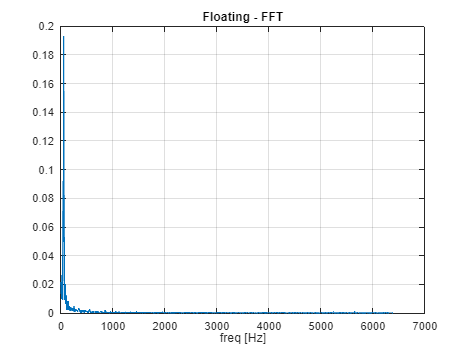

ans =     0.0215
    0.0129
    0.0102
    0.0266
    0.0218
    0.0096
    0.0541
    0.0925
    0.1927
    0.0880


figure;
plot(FREQ(1:FFT_triming), abs(FFT_float.values(1:FFT_triming, 1, MEASURE_POINT)))
title(FFT_float.title)
xlabel("freq [Hz]"), grid on;

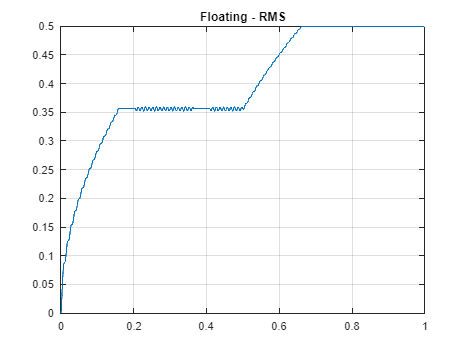

figure;
plot(TIME2, RMS_float.values(:, :))
title(RMS_float.title), grid on;

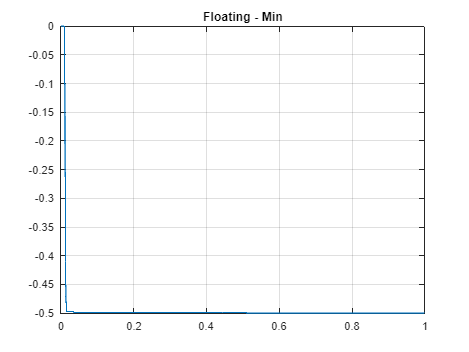


figure;
plot(TIME2, MIN_float.values(:, :))
title(Type + MIN_float.title), grid on;

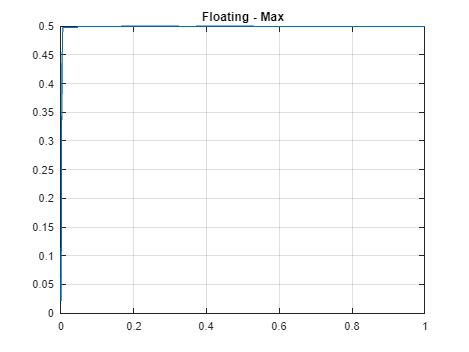


figure;
plot(TIME2, MAX_float.values(:, :))
title(Type + MAX_float.title), grid on;

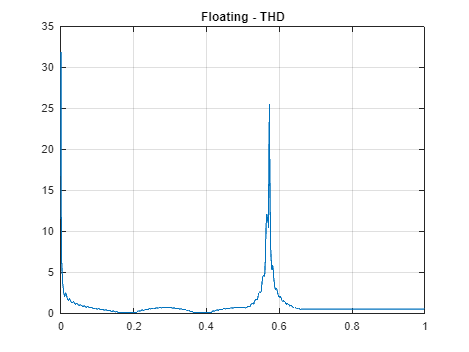

Type


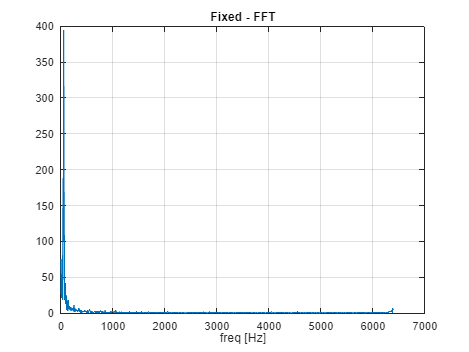

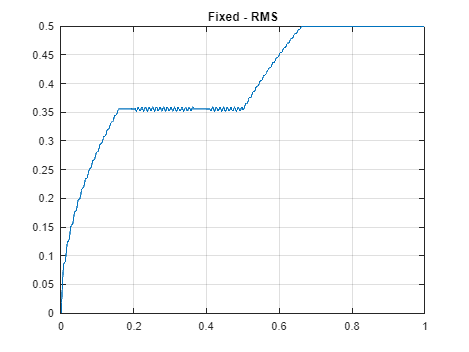

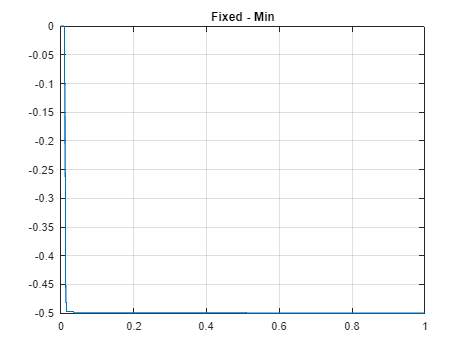

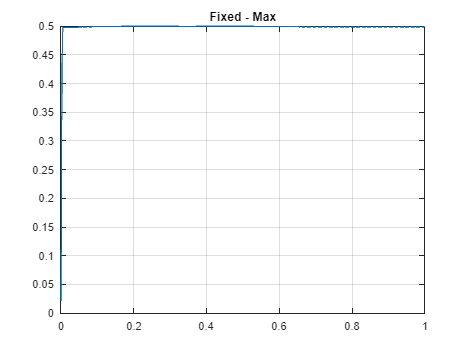

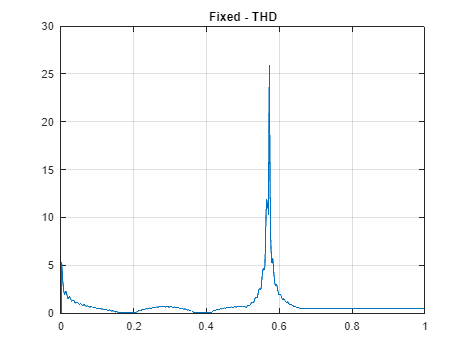


figure;
plot(TIME2, THD_float.values(:,:))
title(Type + THD_float.title), grid on;

Diff

Type = "Fixed - Float difference | - "

Type = "Fixed - Float difference - "

disp(Type);

Fixed - Float difference - 


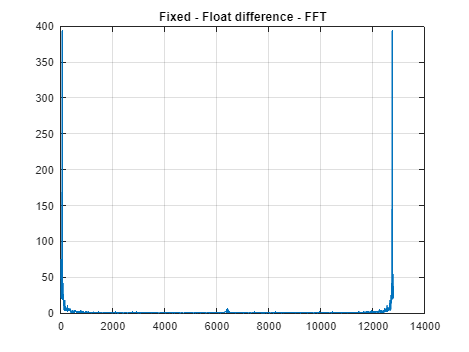

fft_diff = abs(fi(FFT_fixed.values(1:end, 1, MEASURE_POINT)) - FFT_float.values(1:end, 1, MEASURE_POINT));
figure;
plot(FREQ, fft_diff);
title(Type + FFT_fixed.title), grid on;

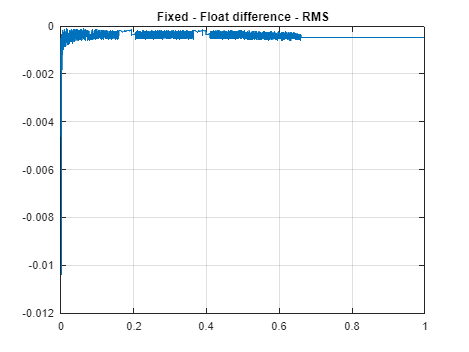


figure;
plot(TIME2, RMS_fixed.values(:, :) - RMS_float.values(:, :))
title(Type + RMS_fixed.title), grid on;

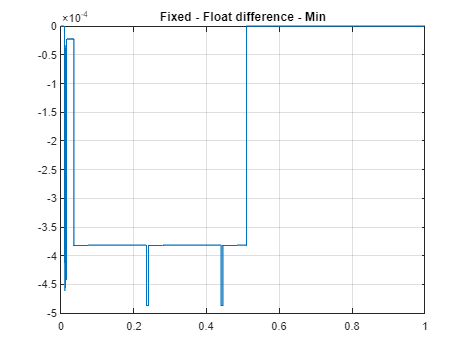


figure;
plot(TIME2, MIN_fixed.values(:, :) - MIN_float.values(:, :))
title(Type + MIN_fixed.title), grid on;

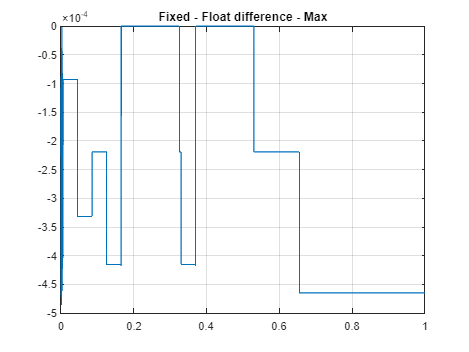


figure;
plot(TIME2, MAX_fixed.values(:, :) - MAX_float.values(:, :))
title(Type + MAX_fixed.title), grid on;

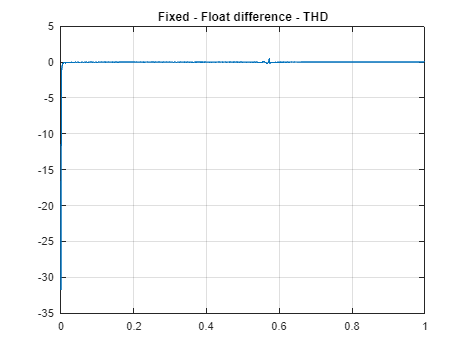


figure;
plot(TIME2, THD_fixed.values(:, :) - THD_float.values(:, :))
title(Type + THD_fixed.title), grid on;

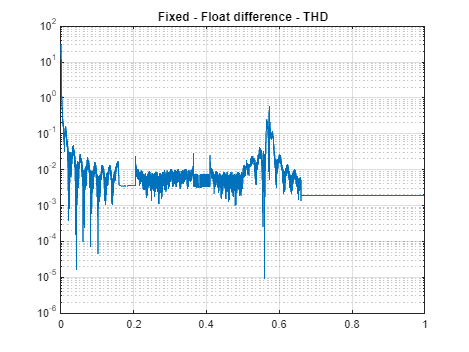


figure;
semilogy(TIME2, abs(THD_fixed.values(:, :) - THD_float.values(:, :)))
title(Type + THD_fixed.title), grid on;

%slidePlot(abs(FFT_fixed.values(1:1024, :, :)));
%slidePlot(abs(BUF_fixed.values(1:1024, :, :)));